p =   QuantumCircuitChart with properties:

                 Gates: [1×1 quantum.gate.SimpleGate]
             NumQubits: 1
           QubitBlocks: [1×0 double]
               NumRows: 1
    QubitLabelLocation: "none"

  Show all properties


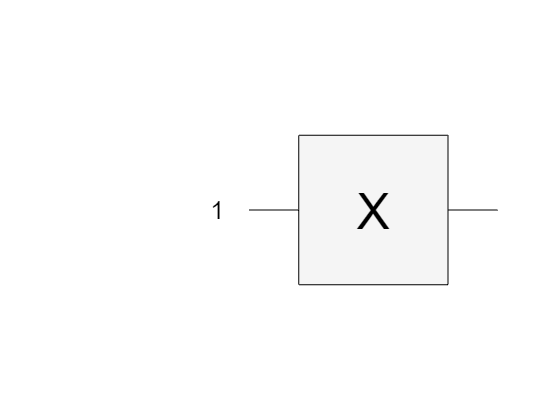

print_once = 1

Input |0>, Output 1
Input |1>, Output 0


clear all;
print_once = 0;
for i=["0", "1"]
    [qc, out] = NOT(i);
    if print_once == 0
        figure
        p = plot(qc)
        p.QubitLabelLocation = "left";
        print_once = 1
    end
    fprintf("Input |%s>, Output %s\n",i, out);
end

p =   QuantumCircuitChart with properties:

                 Gates: [2×1 quantum.gate.SimpleGate]
             NumQubits: 4
           QubitBlocks: [1×0 double]
               NumRows: 1
    QubitLabelLocation: "none"

  Show all properties


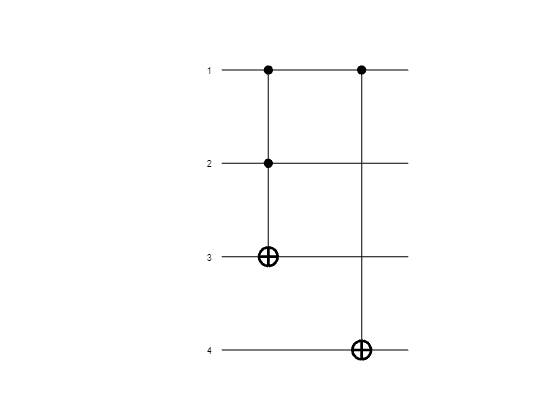

print_once = 1

Input |00>, Output 0, Ancillary 0
Input |01>, Output 0, Ancillary 0
Input |10>, Output 0, Ancillary 1
Input |11>, Output 1, Ancillary 1


print_once = 0;
for i=["00", "01", "10", "11"]
    [qc, out] = AND(i);
    if print_once == 0
        figure
        p = plot(qc)
        p.QubitLabelLocation = "left";
        print_once = 1
    end
    ch = char(out);
    fprintf("Input |%s>, Output %s, Ancillary %s\n",i, ch(3), ch(4));
end

p =   QuantumCircuitChart with properties:

                 Gates: [3×1 quantum.gate.SimpleGate]
             NumQubits: 4
           QubitBlocks: [1×0 double]
               NumRows: 1
    QubitLabelLocation: "none"

  Show all properties


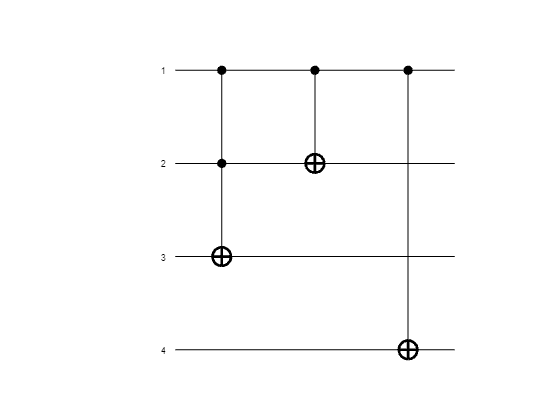

print_once = 1

Input |00>, Output 00, Ancilla 0
Input |01>, Output 01, Ancilla 0
Input |10>, Output 01, Ancilla 1
Input |11>, Output 10, Ancilla 1


print_once = 0;
for i=["00", "01", "10", "11"]
    [qc, out] = ADDER(i);
    if print_once == 0
        figure
        p = plot(qc)
        p.QubitLabelLocation = "left";
        print_once = 1
    end
    ch = char(out);
    fprintf("Input |%s>, Output %s%s, Ancilla %s\n",i, ch(3),ch(2), ch(4)); % flip because of measurement order

end

## Fredkin Gate


$$\matrix {
\text{Input}    	& & & \text{Output}  \cr
C & I_1 & I_2 & C & O_1 & O_2 \cr
0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 1 & 0 & 0 & 1 \cr
0 & 1 & 0 & 0 & 1 & 0 \cr
0 & 1 & 1 & 0 & 1 & 1 \cr
1 & 0 & 0 & 1 & 0 & 0 \cr
1 & 0 & 1 & 1 & 1 & 0 \cr
1 & 1 & 0 & 1 & 0 & 1 \cr
1 & 1 & 1 & 1 & 1 & 1 \cr
}$$


p =   QuantumCircuitChart with properties:

                 Gates: [17×1 quantum.gate.SimpleGate]
             NumQubits: 3
           QubitBlocks: [1×0 double]
               NumRows: 1
    QubitLabelLocation: "none"

  Show all properties


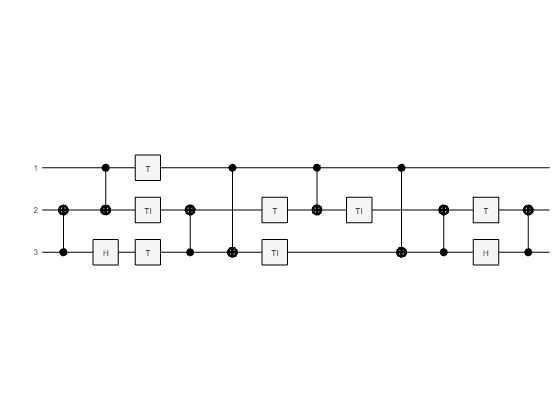

Input |000>, Output 000
Input |001>, Output 001
Input |010>, Output 010
Input |011>, Output 011
Input |100>, Output 100
Input |101>, Output 110
Input |110>, Output 101
Input |111>, Output 111


print_once = 0;
for i=["000", "001", "010", "011","100", "101", "110", "111"]
    [qc, out] = Fredkin(i);
    if print_once == 0
        figure
        p = plot(qc)
        print_once =1;
        p.QubitLabelLocation = "left";
    end
    fprintf("Input |%s>, Output %s\n",i, out); % flip because of measurement order
end

function [qc, output] = NOT(inp)
    % An NOT gate.
    % 
    % Parameters:
    %     inp (str): Input, encoded in qubit 0.
    % 
    % Returns:
    %     QuantumCircuit: Output NOT circuit.
    %     str: Output value measured from qubit 0.
    %

    qc = quantumCircuit (1); % A quantum circuit with a single qubit and a single classical bit

    % Now we've encoded the input, we can do a NOT on it using x
    qc.Gates = [xGate(1)];

    S = simulate(qc,inp);

    [output,probabilities] = querystates(S);
end

function [qc, output] = AND(inp)
    % An AND gate.
    % 
    % Parameters:
    %     inp1 (str): Input, encoded in qubit 0.
    %     inp2 (str): Input, encoded in qubit 1.
    % 
    % Returns:
    %     QuantumCircuit: Output AND circuit.
    %     str: Output value measured from qubit 01.
    % 
    qc = quantumCircuit(4); % A quantum circuit with a 4 qubits and two classical bit

    % Now we've encoded the input, we can do a reversible AND on it using ccx and cx
    % ccx does the AND and cx carrys the state of q0 to guarentee reversibility 
    qc.Gates = [ccxGate(1,2,3);
                cxGate(1,4)];
    
    S = simulate(qc,inp+"00");

    [output,probabilities] = querystates(S);
    
end

function [qc, output] = ADDER(inp)
    % An ADDER
    % 
    % Parameters:
    %     inpt1 (str): Input 1, encoded in qubit 0.
    %     inpt2 (str): Input 2, encoded in qubit 1.
    % 
    % Returns:
    %     QuantumCircuit: Output ADDER circuit.
    %     str: Output value measured from qubit 2.
    %
    qc = quantumCircuit(4); 
       

    % this is where your program for quantum AND gate goes

    qc.Gates = [ccxGate(1, 2, 3); 
                cxGate(1, 2); 
                cxGate(1,4)];

    S = simulate(qc,inp+"00");

    [output,probabilities] = querystates(S);
end


function [qc, output] = Fredkin(inp)
    % An Fredkin
    % 
    % Parameters:
    %     inpt1 (str): Input 1, encoded in qubit 0.
    %     inpt2 (str): Input 2, encoded in qubit 1.
    %     inpt3 (str): Input 3, encoded in qubit 2.
    % 
    % Returns:
    %     QuantumCircuit: Output Fredkin circuit.
    %     str: Output value measured .
    % 

    qc = quantumCircuit(3); 


    % this is where your program for quantum AND gate goes

    qc.Gates = [cxGate(3, 2); 
                cxGate(1, 2); 
                hGate(3); 
                tGate(1);
                tiGate(2);
                tGate(3);
                cxGate(3, 2); 
                cxGate(1, 3); 
                tGate(2);
                cxGate(1, 2); 
                tiGate(3);
                tiGate(2);
                cxGate(1, 3);
                cxGate(3, 2);
                tGate(2);
                hGate(3);
                cxGate(3, 2)];

  
    S = simulate(qc,inp);

    [output,probabilities] = querystates(S);
end